OutputFolder = 'E:\165566_377107_bundle_archive\photo';  % Set as needed [EDITED]
dinfo = dir('*.jpg');% image extension
k = imread('pro 2.jpeg');

feat=[];
for K = 1 : length(dinfo)
  thisimage = dinfo(K).name;
  I   = imread('pro 2.jpeg');
 
  % Segmentation using RegionGrowing
  x=198; y=198;
  I =im2double(I)
  
  J = regiongrowing(I,x,y,0.2);
  
  % Morphological Operation
  tumor = imopen(J,strel('line',15,0));
  % DWT
  [cA1,cH1,cV1,cD1] = dwt2(tumor,'db4');
  [cA2,cH2,cV2,cD2] = dwt2(cA1,'db4');
  DWT_feat = [cA2,cH2,cV2,cD2];
  G = pca(DWT_feat);
  whos DWT_feat
  whos G
  g = graycomatrix(G);
  stats = graycoprops(g,'Contrast Correlation Energy Homogeneity');
  Contrast = stats.Contrast;
  Correlation = stats.Correlation;
  Energy = stats.Energy;
  Homogeneity = stats.Homogeneity;
  %D = abs(I-G).^2;
  %MSE = sum(D(:))/numel(I)
  %PSNR=10*log(255*255/MSE)

  feat = [feat;Contrast Correlation Energy Homogeneity];
end

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

  Name           Size              Bytes  Class     Attributes

  DWT_feat      85x276            187680  double              



  Name        Size             Bytes  Class     Attributes

  G         276x84            185472  double              



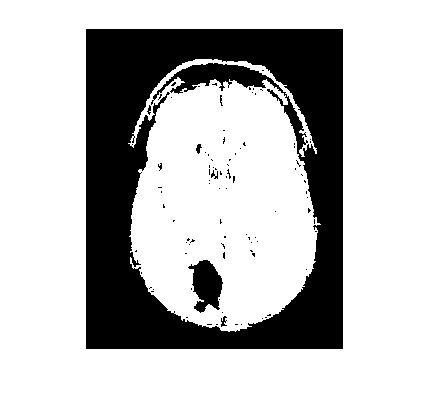

imshow(J)

feat= transpose(feat)

feat =     0.0967    0.0967    0.0967    0.0967    0.0967    0.0967
    0.1146    0.1146    0.1146    0.1146    0.1146    0.1146
    0.8898    0.8898    0.8898    0.8898    0.8898    0.8898
    0.9713    0.9713    0.9713    0.9713    0.9713    0.9713


 xdata = feat;
 w = 30;
 n = 2;
 v = repmat(1:n,[w 1])

v =      1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2
     1     2


 group = v(:)'

group =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2     2


 
 
 
%  OutputFolder = 'C:\Users\Himani Narain\Documents\MATLAB\Test';  % Set as needed [EDITED]
% dinfo = dir('*.jpg');% image extension
% feat2=[];
% for K = 1 : length(dinfo)
%   thisimage = dinfo(K).name;
%   I   = imread(thisimage)
%   
%   % Segmentation using RegionGrowing
%   x=198; y=198;
%   I =im2double(I)
%   J = regiongrowing(I,x,y,0.2);
%   % Morphological Operation
%   tumor = imopen(J,strel('line',15,0));
%   % DWT
%   [cA1,cH1,cV1,cD1] = dwt2(tumor,'db4');
%   [cA2,cH2,cV2,cD2] = dwt2(cA1,'db4');
%   DWT_feat = [cA2,cH2,cV2,cD2];
%   G = pca(DWT_feat);
%   whos DWT_feat
%   whos G
%   g = graycomatrix(G);
%   stats = graycoprops(g,'Contrast Correlation Energy Homogeneity');
%   Contrast = stats.Contrast;
%   Correlation = stats.Correlation;
%   Energy = stats.Energy;
%   Homogeneity = stats.Homogeneity;
%   %D = abs(I-G).^2;
%   %MSE = sum(D(:))/numel(I)
%   %PSNR=10*log(255*255/MSE)
% 
%   feat2 = [feat;Contrast Correlation Energy Homogeneity];
% end
% feat2= transpose(feat2)
 

function J=regiongrowing(I,x,y,reg_maxdist)
% This function performs "region growing" in an image from a specified
% seedpoint (x,y)
%
% J = regiongrowing(I,x,y,t) 
% 
% I : input image 
% J : logical output image of region
% x,y : the position of the seedpoint (if not given uses function getpts)
% t : maximum intensity distance (defaults to 0.2)
%
% The region is iteratively grown by comparing all unallocated neighbouring pixels to the region. 
% The difference between a pixel's intensity value and the region's mean, 
% is used as a measure of similarity. The pixel with the smallest difference 
% measured this way is allocated to the respective region. 
% This process stops when the intensity difference between region mean and
% new pixel become larger than a certain treshold (t)
%
% Example:
%
% I = im2double(imread('medtest.png'));
% x=198; y=359;
% J = regiongrowing(I,x,y,0.2); 
% figure, imshow(I+J);
%
% Author: D. Kroon, University of Twente

if(exist('reg_maxdist','var')==0), reg_maxdist=0.2; end
if(exist('y','var')==0), figure, imshow(I,[]); [y,x]=getpts; y=round(y(1)); x=round(x(1)); end

J = zeros(size(I)); % Output 
Isizes = size(I); % Dimensions of input image

reg_mean = I(x,y); % The mean of the segmented region
reg_size = 1; % Number of pixels in region

% Free memory to store neighbours of the (segmented) region
neg_free = 10000; neg_pos=0;
neg_list = zeros(neg_free,3); 

pixdist=0; % Distance of the region newest pixel to the regio mean

% Neighbor locations (footprint)
neigb=[-1 0; 1 0; 0 -1;0 1];

% Start regiogrowing until distance between regio and posible new pixels become
% higher than a certain treshold
while(pixdist<reg_maxdist&&reg_size<numel(I))

    % Add new neighbors pixels
    for j=1:4
        % Calculate the neighbour coordinate
        xn = x +neigb(j,1); yn = y +neigb(j,2);
        
        % Check if neighbour is inside or outside the image
        ins=(xn>=1)&&(yn>=1)&&(xn<=Isizes(1))&&(yn<=Isizes(2));
        
        % Add neighbor if inside and not already part of the segmented area
        if(ins&&(J(xn,yn)==0)) 
                neg_pos = neg_pos+1;
                neg_list(neg_pos,:) = [xn yn I(xn,yn)]; J(xn,yn)=1;
        end
    end

    % Add a new block of free memory
    if(neg_pos+10>neg_free), neg_free=neg_free+10000; neg_list((neg_pos+1):neg_free,:)=0; end
    
    % Add pixel with intensity nearest to the mean of the region, to the region
    dist = abs(neg_list(1:neg_pos,3)-reg_mean);
    [pixdist, index] = min(dist);
    J(x,y)=2; reg_size=reg_size+1;
    
    % Calculate the new mean of the region
    reg_mean= (reg_mean*reg_size + neg_list(index,3))/(reg_size+1);
    
    % Save the x and y coordinates of the pixel (for the neighbour add proccess)
    x = neg_list(index,1); y = neg_list(index,2);
    
    % Remove the pixel from the neighbour (check) list
    neg_list(index,:)=neg_list(neg_pos,:); neg_pos=neg_pos-1;
end

% Return the segmented area as logical matrix
J=J>1;

end 


